## Generate Velocity Field

Perlin Noise Settings

seed        =   32;
size        =  512;
n_tiles     =     5;
n_octaves   =   28;
persistence = 0.706;
ammountN    =  64.7;

Centripetal Force Settings

ammountC    =  10.8;

Simulation Settings

vel         = 9.2;
n_particles = 5950000;
END_TIME =     100;

Generate Perlin Noise [1]

rng(seed);
Psi_N     = zeros(size);
idxs      = 1:n_octaves;
max_amp   = sum(persistence.^(idxs-1));

for i = idxs
    Psi_N = Psi_N + ...
        imresize(rand(n_tiles*i), ...
                [size size],"cubic")*...
        persistence^(i-1)/...
        max_amp;
end
Psi_N = Psi_N/n_tiles;

Generate Centripetal Force Potential

x = (1:size)/size-1/2;
y = (1:size)/size-1/2;
PsiP = sqrt(x.^2+transpose(y.^2));

Superposition of Potentials

Psi = vel*(Psi_N*ammountN+PsiP*ammountC);

Generate Velocity Field [2]

[dPsidx,dPsidy] = gradient(Psi);
vx =   dPsidx*size;
vy =  -dPsidy*size;

## Particle Simulation

Initialization

dt = 1/60;
[px,pidxs] = sort(size*rand(n_particles,1));
py = size*rand(n_particles,1);
pc = 1:n_particles;
pc = pc(pidxs);

Simulation

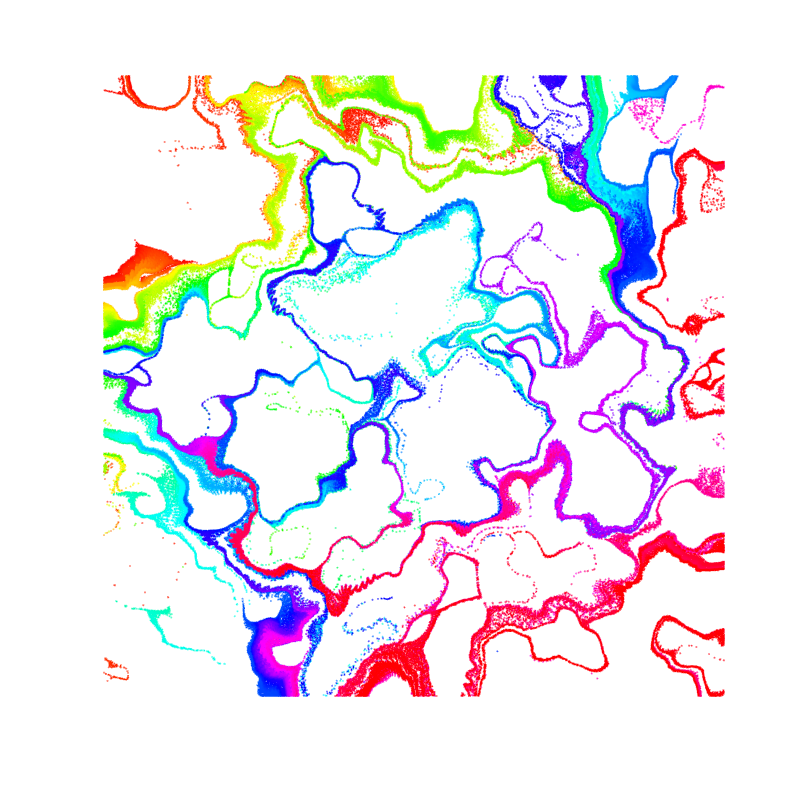

fig = figure('Position',[0,0,800,800]);
for t = 1:END_TIME
    px_grid = round(px);
    py_grid = round(py);
        
    px_grid(px_grid<1) = 1;
    px_grid(size<px_grid) = size;

    py_grid(py_grid<1) = 1;
    py_grid(size<py_grid) = size;
    
    cla
    scatter(px,py,1,pc,".","CData",hsv(n_particles));
    gca.color = "black";
    xlim([0 size]);
    ylim([0 size]);
    pbaspect([1 1 1]);
    axis off
    drawnow;
        
    for i = 1:n_particles
        pvx = vx(px_grid(i),py_grid(i));
        pvy = vy(px_grid(i),py_grid(i));
        
        px(i) = px(i) + pvx * dt;
        py(i) = py(i) + pvy * dt;
    end 
end

## Reference

[1] Perlin Noise, [https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm](https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm)

[2] Bridson, R., Houriham, J., & Nordenstam, M. (2007). Curl-noise for procedural fluid flow. *ACM Transactions on Graphics (ToG)*, *26*(3), 46-es.